data = load("statisk11.mat");

ax = data.Acceleration.(1);
ay = data.Acceleration.(2);
az = data.Acceleration.(3);

plot(ax);

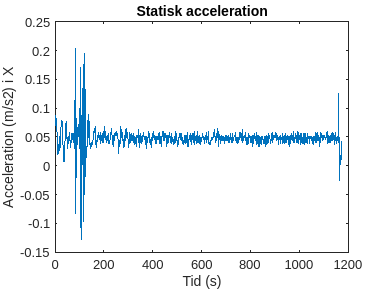

xlabel("Tid (s)")
ylabel("Acceleration (m/s2) i X")
title("Statisk acceleration")

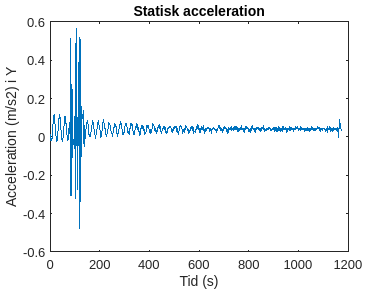


plot(ay);
xlabel("Tid (s)")
ylabel("Acceleration (m/s2) i Y")
title("Statisk acceleration")

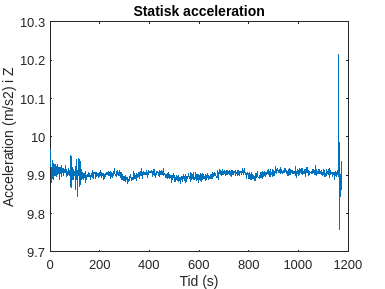


plot(az);
title("Statisk acceleration")
xlabel("Tid (s)")
ylabel("Acceleration (m/s2) i Z")

Drop

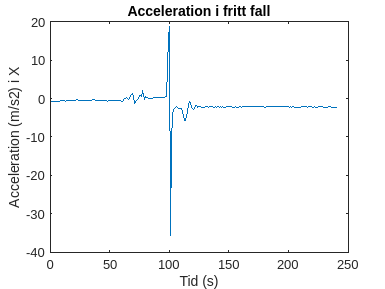

data = load("drop.mat");

ax = data.Acceleration.(1);
ay = data.Acceleration.(2);
az = data.Acceleration.(3);

plot(ax);
xlabel("Tid (s)")
ylabel("Acceleration (m/s2) i X")
title("Acceleration i fritt fall")

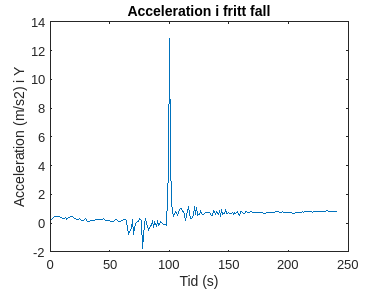


plot(ay);
xlabel("Tid (s)")
ylabel("Acceleration (m/s2) i Y")
title("Acceleration i fritt fall")

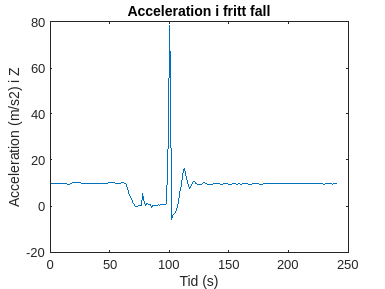


plot(az);
title("Acceleration i fritt fall")
xlabel("Tid (s)")
ylabel("Acceleration (m/s2) i Z")

Statisk2

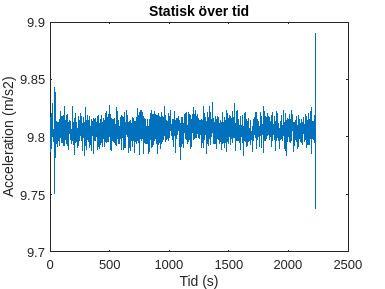

data = load("accelerationtid.mat");
az = data.Acceleration.(3);

plot(az);
xlabel("Tid (s)")
ylabel("Acceleration (m/s2)")
title("Statisk över tid")



az3 = mean(az(1:3));
az5 = mean(az(1:5));
az10 = mean(az(1:10));
az20 = mean(az(1:20));
az100 = mean(az(1:100));
az1000 = mean(az(1:1000));

az3s = std(az(1:3));
az5s = std(az(1:5));
az10s = std(az(1:10));
az20s = std(az(1:20));
az100s = std(az(1:100));
az1000s = std(az(1:1000));

disp("Medelvärde")

Medelvärde


disp(az3)

    9.8077



disp(az5)

    9.8050



disp(az10)

    9.8041



disp(az20)

    9.8052



disp(az100)

    9.8057



disp(az1000)

    9.8059




disp("Standardavvikelse")

Standardavvikelse


disp(az3s)

    0.0095



disp(az5s)

    0.0122



disp(az10s)

    0.0123



disp(az20s)

    0.0098



disp(az100s)

    0.0117



disp(az1000s)

    0.0083



histo

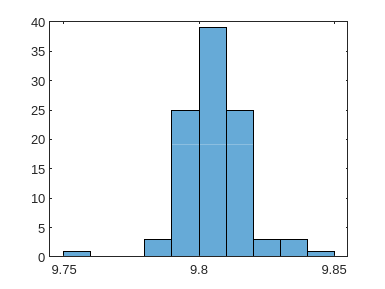

az = az(1:100);

hist = histogram(az);
hold on;


pd = fitdist(az, 'Normal');

fitdist requires Statistics and Machine Learning Toolbox.


x_values = linspace(min(az), max(az), 100);
pd_norm = pdf(pd, x_values);

plot(x_values, pd_norm, 'b', 'LineWidth', 2);

